# Figures 1,2,3

Chapter: Visual Encoding Authors: Wandell, Brainard, Cottaris Editor: Spitschan

Include ISETBio on your path.

%{
thisDir = '/Volumes/GoogleDrive/My Drive/Papers/Book Chapters/2021 Circadian Functions (Spitschan)';
chdir(thisDir)
%}

## Figure 1:  Display radiance

A display emits a spectral radiance from each small spatial region $r(x,y)$. Within each region (pixel) the display radiance is the weighted sum of the emissions of the display primaries (plus potentially some amount of reflected ambient light, not shown). The radiance from each region is the weighted sum of the primaries, and the weights depend on the image. The rays are emitted in many directions, and only a small fraction of the ray bundle reaches the cornea, forming the incident light field. The physiological optics (cornea and lens) transform the light at the cornea into the retinal irradiance. The lens of the eye accommodates to focus the relevant portion of the image at the cone inner segment layer.

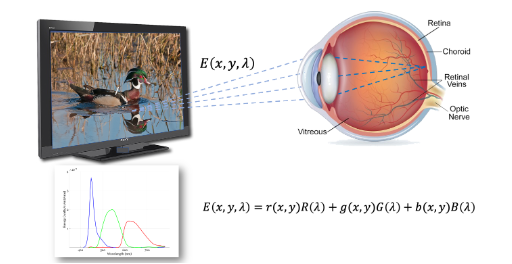

% Create the scene from the file
displayName = 'LCD-Apple';
scene = sceneFromFile('woodDuck.png','rgb',100,displayName);

[vcReadImage] Assuming an 8bit image and a 10 bit LUT


sceneWindow(scene);

We picked a rectangular region for the figure. You can select another region this way:

Or you can use the interactive menus in the window.

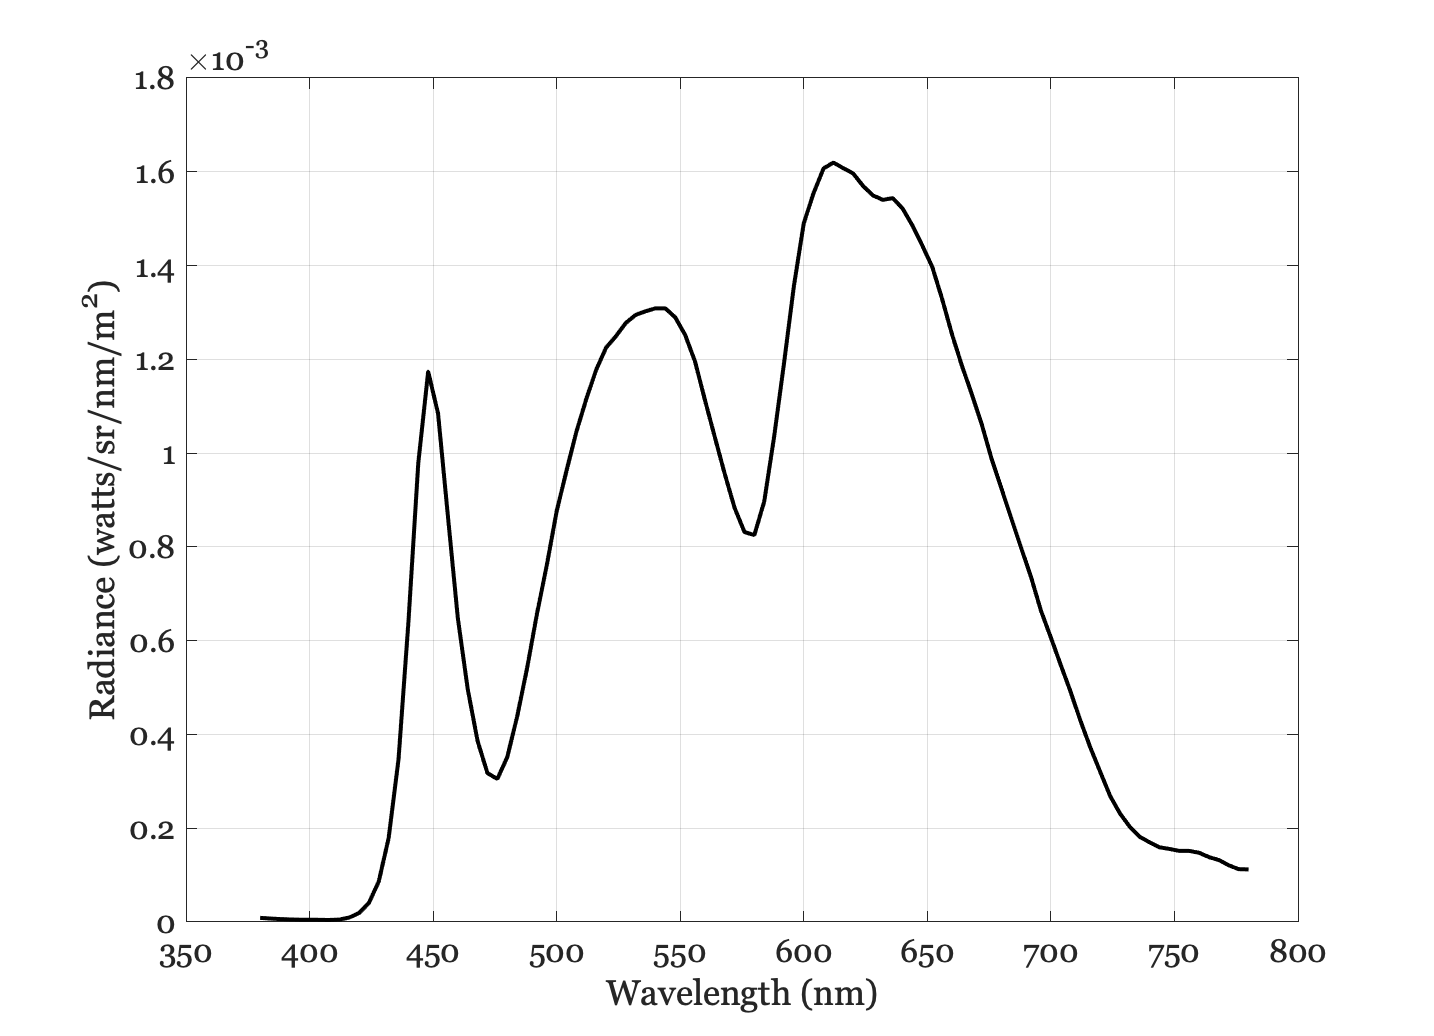

rect = [193 93 120 190];
scenePlot(scene,'radiance energy roi',rect);
thisAx = gca;
thisAx.Children.LineWidth = 2;
thisAx.Children.Color = 'k';

## Figure 2: The natural radiance display

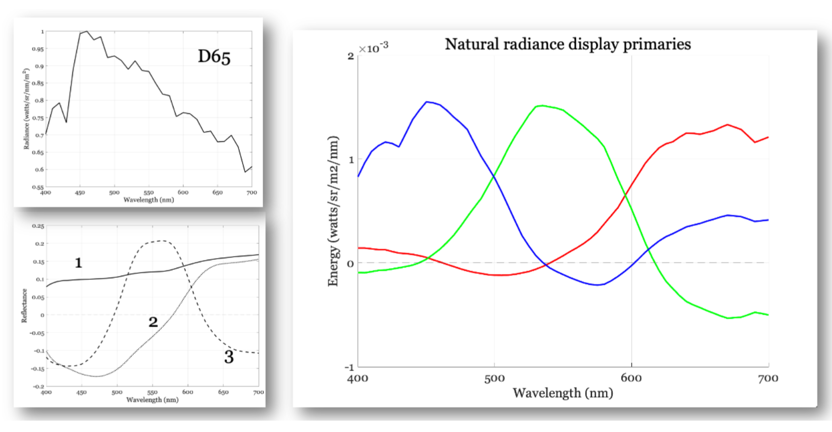

**The natural radiance display. **For most displays the emitted spectral radiance is unlike the spectral radiance observed in nature. It can be useful to convert an RGB image into a scene spectral radiance that matches the appearance on a standard display (sRGB) but that also has a natural spectral radiance. ISETBio includes a method, based on a theoretical display, that accomplishes this. See text for details.

displayName = 'reflectance-display';
scene = sceneFromFile('woodDuck.png','rgb',100,displayName); 

[vcReadImage] Assuming an 8bit image and a 10 bit LUT


sceneWindow(scene);

Here is the illuminant

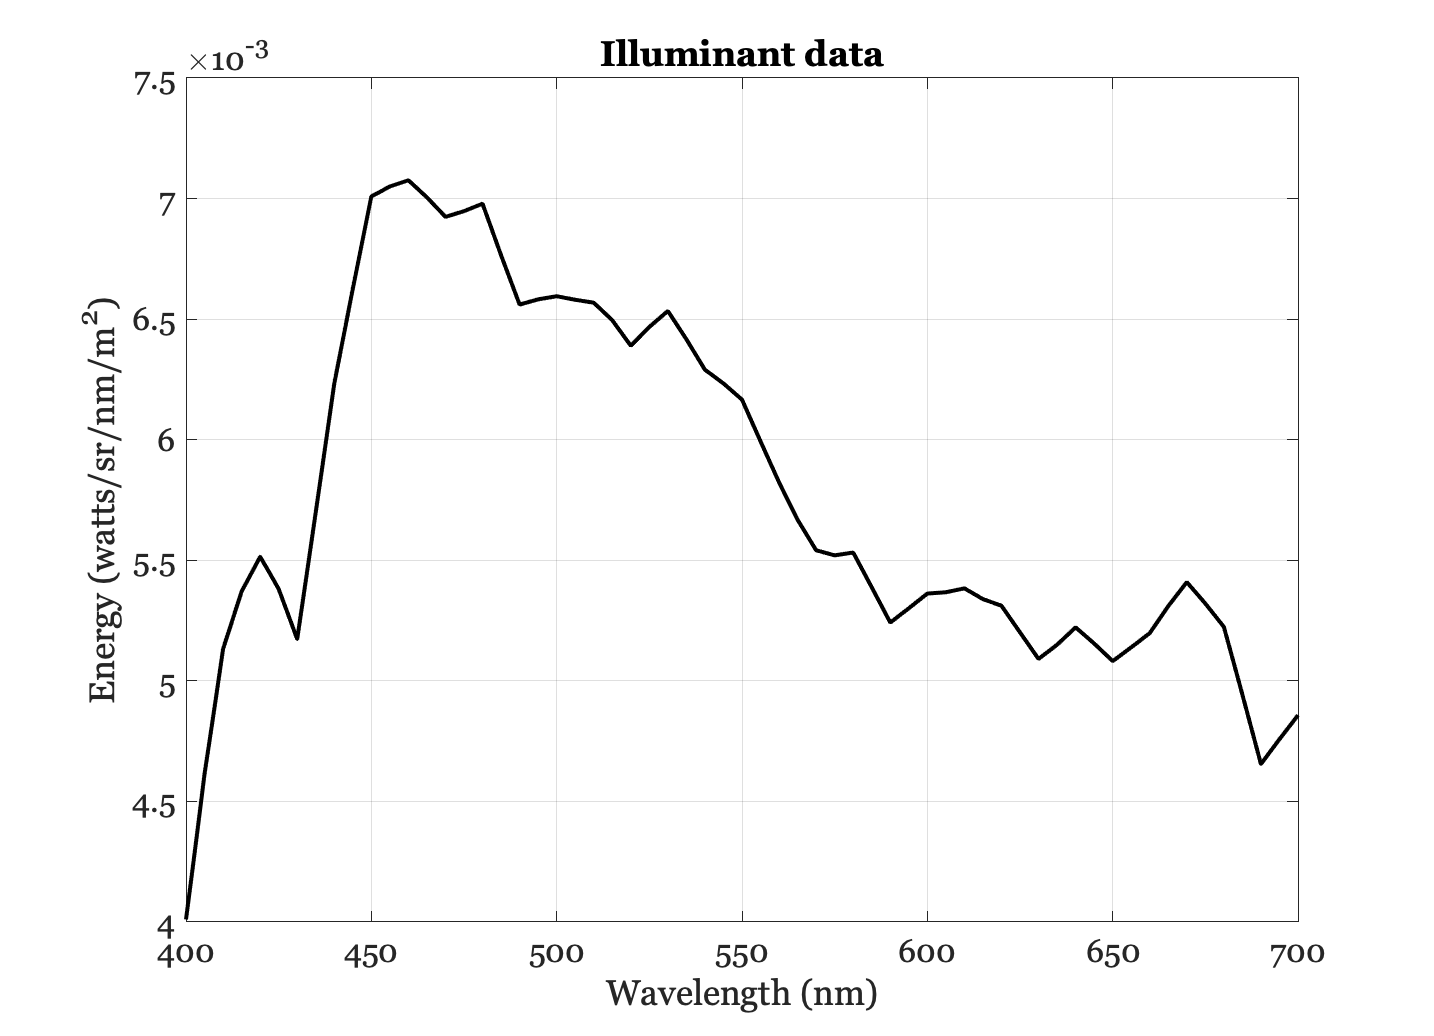

scenePlot(scene,'illuminant energy'); thisAx = gca; thisAx.Children.LineWidth = 2; thisAx.Children.Color = 'k';

Here are the display primaries

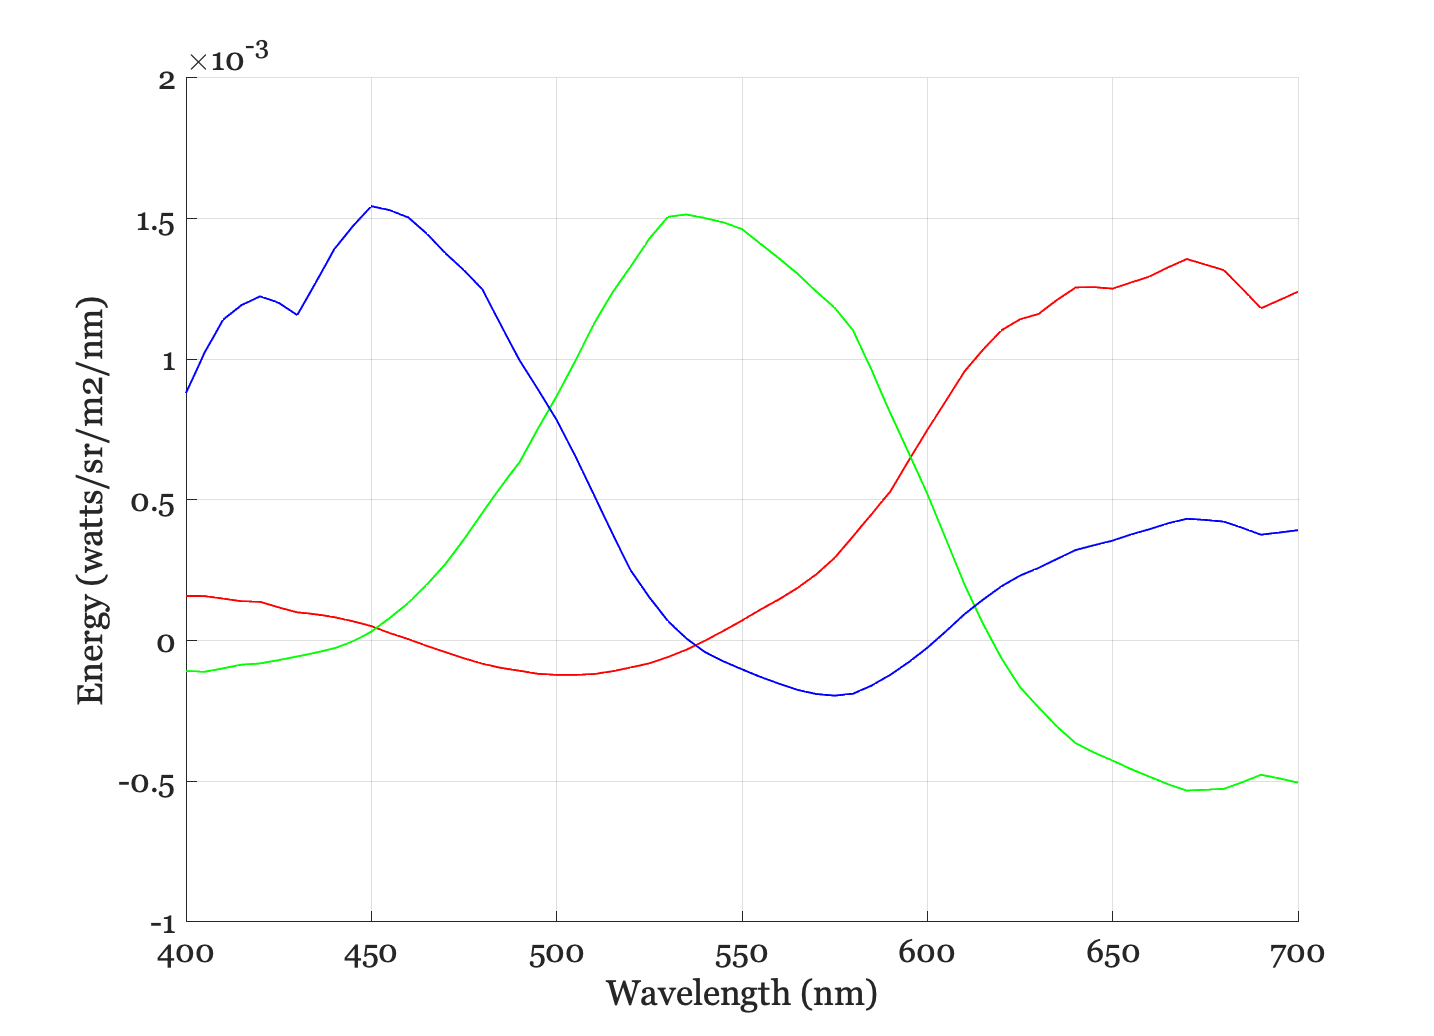

thisDisplay = displayCreate(displayName);
displayPlot(thisDisplay,'primaries');

Here are three basis functions for the natural reflectance space.

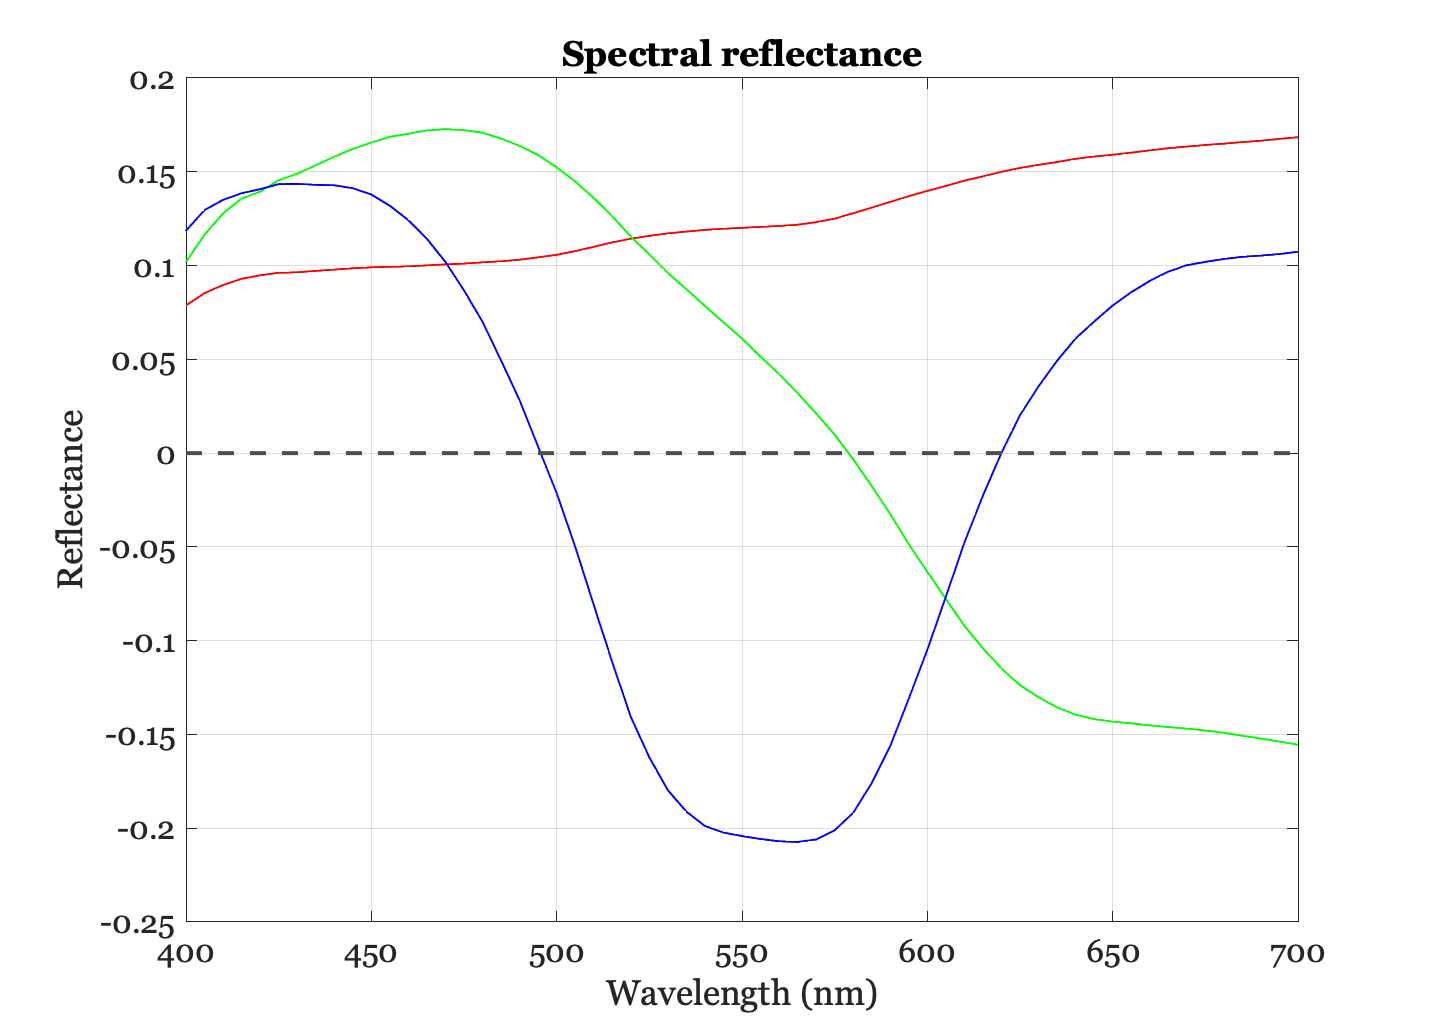

wave = 400:1:700;
basisR = ieReadSpectra('reflectanceBasis',wave);
plotReflectance(wave,-1*basisR(:,1:3));
xaxisLine;

## Figure 3: RGB image data to radiance-display model. 

ISETBio converts rgb data from an image file into a spectral scene representation by assuming the image will be shown on a calibrated display. The three images render the same rgb data on different calibrated displays. The mean spectral radiance from a small region (white rectangle) is shown for each display. The left is an LCD, the center an OLED display and the right a theoret- ical display designed to produce scene radiance similar to natural radiances under a D65 illuminant. The images in this figure were produced by transforming the simulated spectral radiances of the several displays into CIE XYZ values. We then created sRGB image files corresponding to each display. The image appearance differences illustrate that copying simply rgb values into the frame buffer generates substantial color appearance differences across the displays. Differences of this magnitude are typical of the variation observed when displaying rgb data without calibrating for the display primaries and other factors.

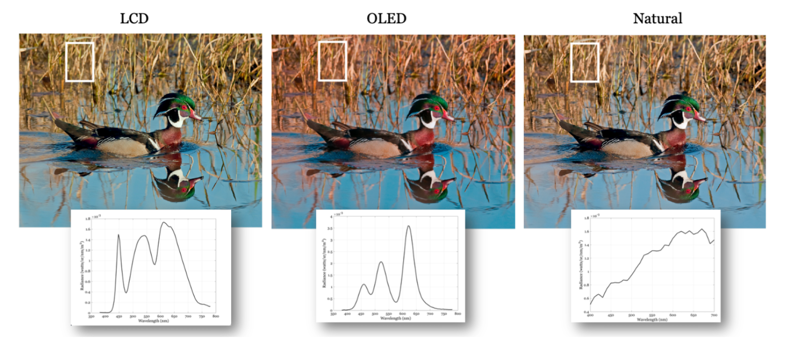

%{
% The same code will run for other displays.  The difference in the modeled
% radiance is substantial.
displayName = 'LCD-Apple';
displayName = 'reflectance-display';
%}
displayName = 'OLED-Samsung';  
scene = sceneFromFile('woodDuck.png','rgb',100,displayName);

[vcReadImage] Assuming an 8bit image and a 10 bit LUT


sceneWindow(scene);

This is the spectral radiance from the same rectangular region.

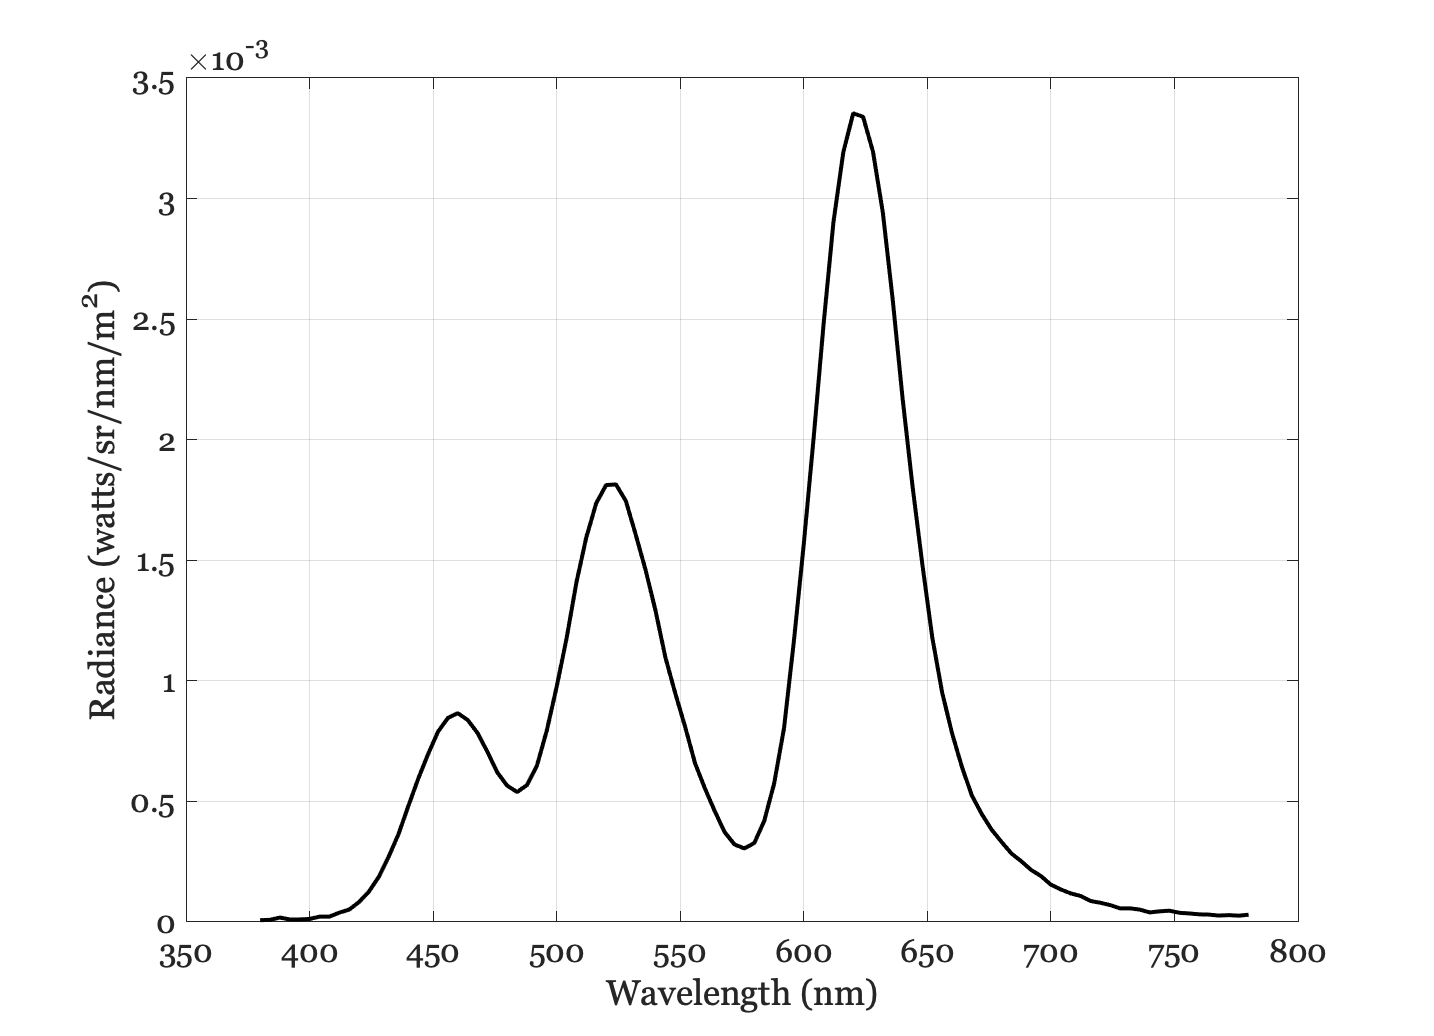

scenePlot(scene,'radiance energy roi',rect);
thisAx = gca; thisAx.Children.LineWidth = 2; thisAx.Children.Color = 'k';